clear all
close all
%data.mat
%Objective of Project: Implement different classifiers to achieve face
%recognition
data = load('data.mat');
face = data.face;
face_neutral = face(:,:,1:3:end);%neutral faces (first face)
face_exp = face(:,:,2:3:end);%smiling faces (second face)
face_illum = face(:,:,3:3:end);%illuminating faces (third face)

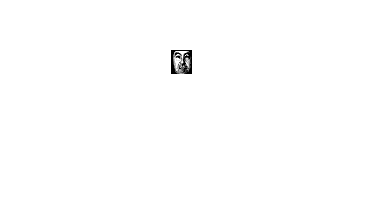

imshow(face(:,:,1));

%200 subjects (people) 
% 3 faces per subject (200*3 = 600 faces)
% size: 24 x 21
% 
% The file 'data.mat' has a variable ”face” of size (24x21x600). The images corresponding to the
% person labeled n, n = {1, . . . , 200}, can be indexed in Matlab as face(:,:,3*n-2), face(:,:,3*n-1)
% and face(:,:,3*n). The first image is a neutral face, the second image is a face with facial
% expression, and the third image has illumination variations.


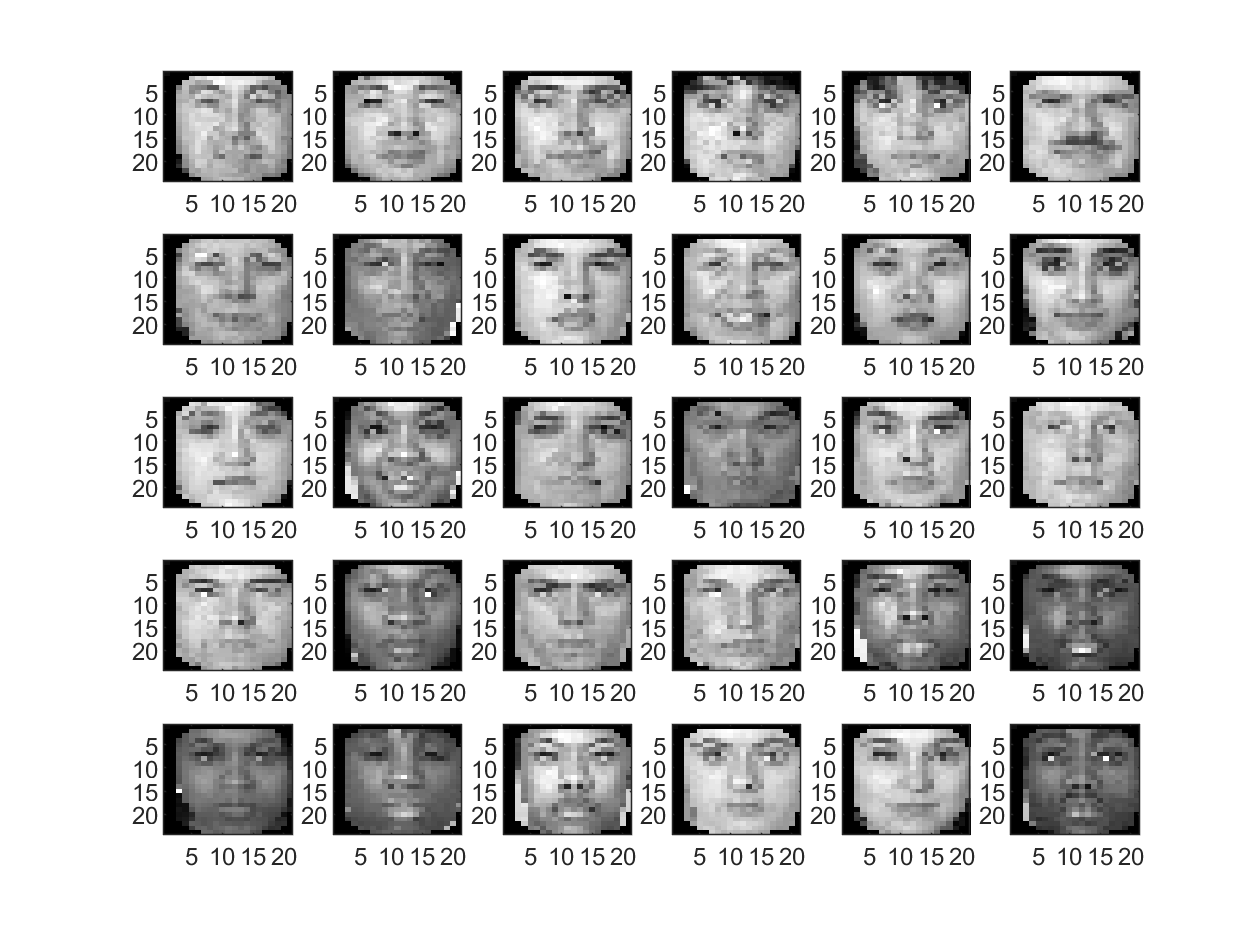

figure;
colormap gray

for j = 1:30
    subplot(5,6,j);
    imagesc(face_neutral(:,:,j));
end

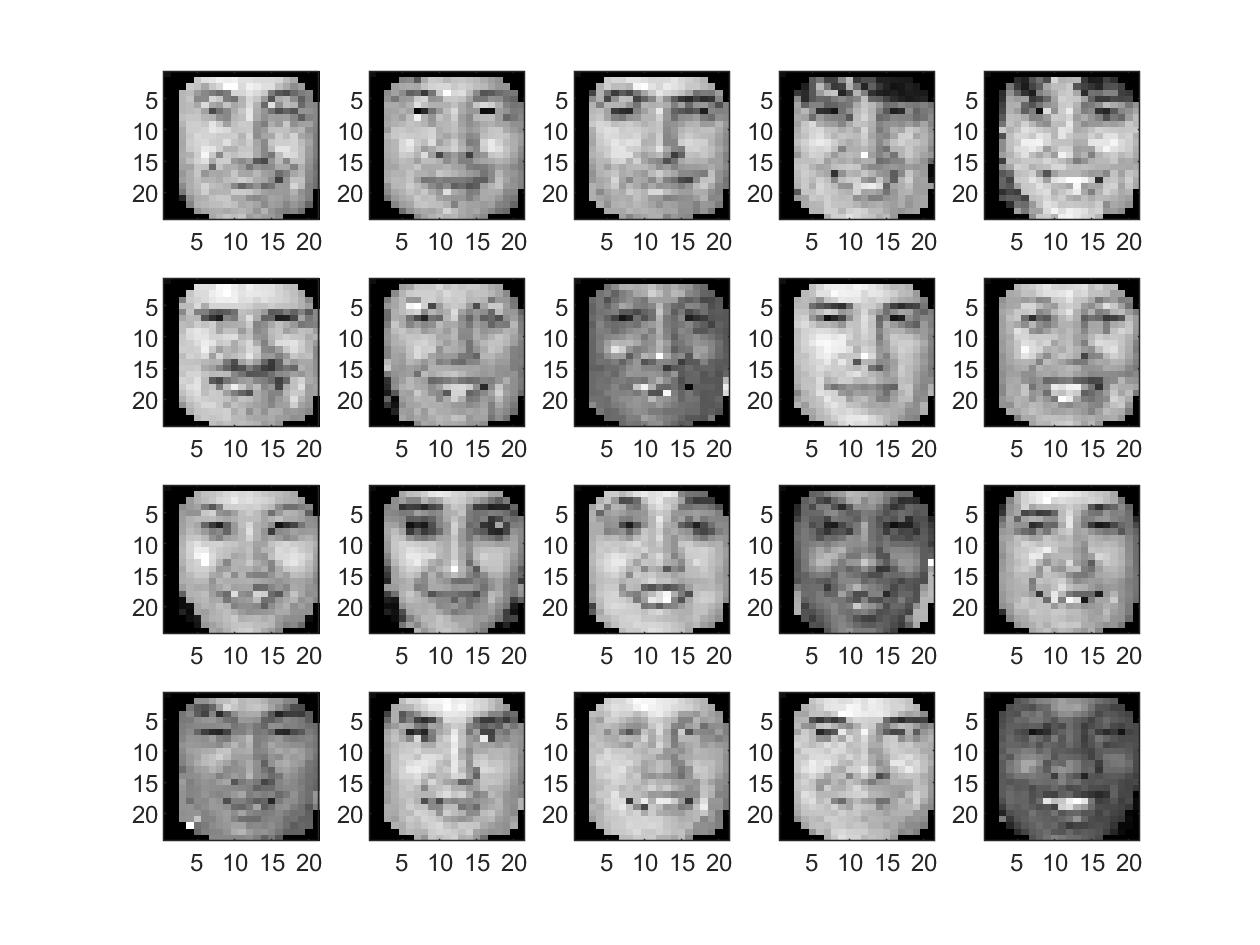


figure;
colormap gray
for j = 1:20
    subplot(4,5,j);
    imagesc(face_exp(:,:,j));
end

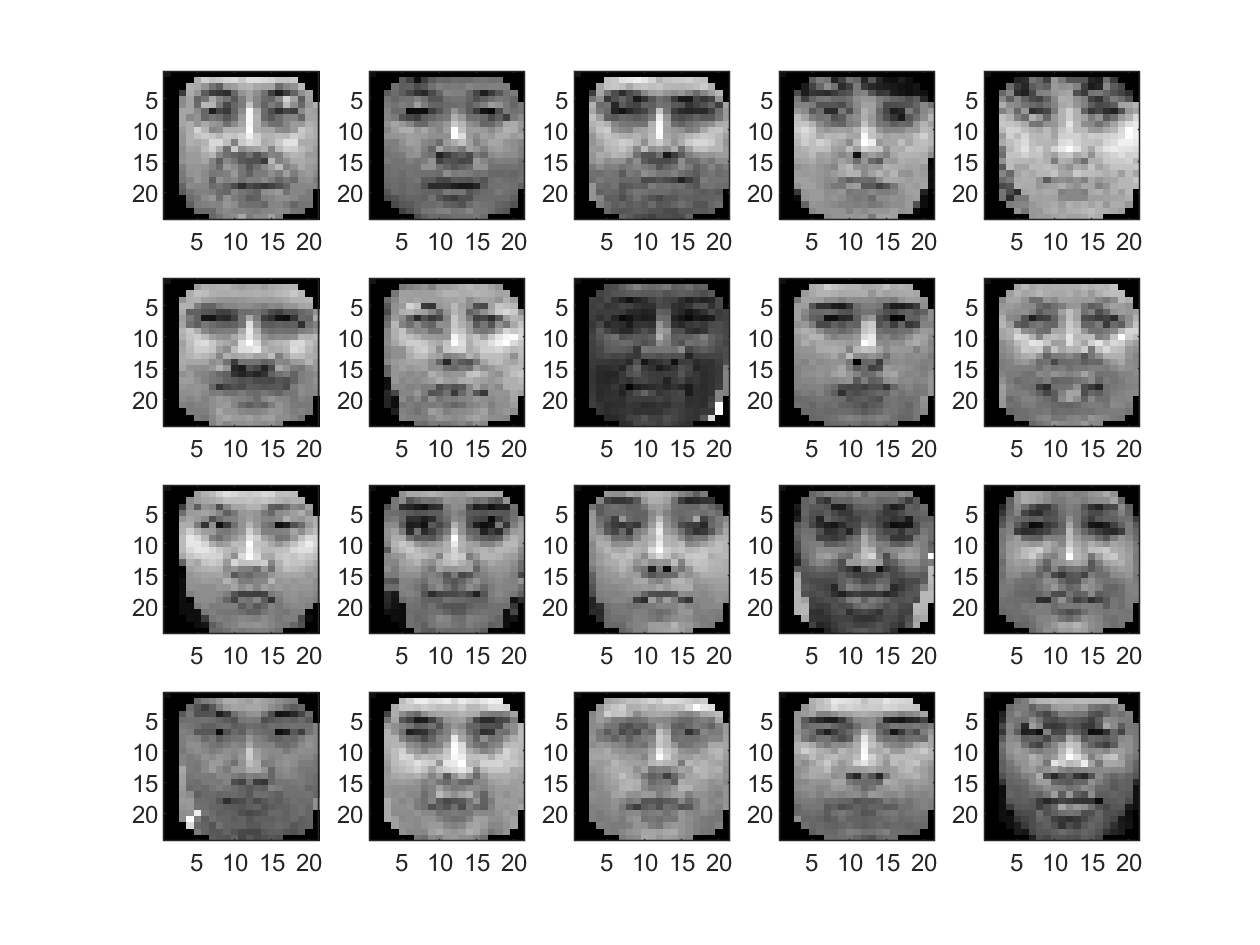


figure;
colormap gray
for j=1:20
    subplot(4,5,j);
    imagesc(face_illum(:,:,j));
end

%face_Neu = face_neutral(:,:,1:100);
%size(face_Neu)

**COMPUTE PCA**

[d1, d2, n] = size(face_neutral); 
X1 = zeros(n,d1*d2);%neutral faces DATA
X2 = zeros(n,d1*d2);%smiling faces DATA
for j = 1:n
    aux = face_neutral(:,:,j);
    X1(j,:) = aux(:)';
    aux = face_exp(:,:,j);
    X2(j,:) = aux(:)';
end


n1 = n;
n2 = n;
meanNeu = mean(X1,1);
meanSmiles = mean(X2,1);
Xc1 = X1-ones(n1,1)*meanNeu; %center X1
S1 = Xc1'*Xc1; %scatter matrix for X1
Xc2 = X2-ones(n2,1)*meanSmiles; %center X2
S2 = Xc2'*Xc2;%scatter matrix for X2
Sw = S1+S2;%compute the within-class scatter

Sb = (meanNeu-meanSmiles)'*(meanNeu-meanSmiles);
[W, lam0] = eig(Sb,Sw);
lam = diag(lam0);
[lam, isort] = sort(lam,'descend');

W = W(:,isort);
W = W(:,1);
X = [X1;X2];
D1 = 1:n1;
D2 = n1+1:n1+n2;
y = X*W;



%Mapping the data to a higher dimensional space -- project to nPCA-dimensional space
[U,Sig,V] = svd(X','econ');
nPCA =20;
Y = X*U(:,1:nPCA);

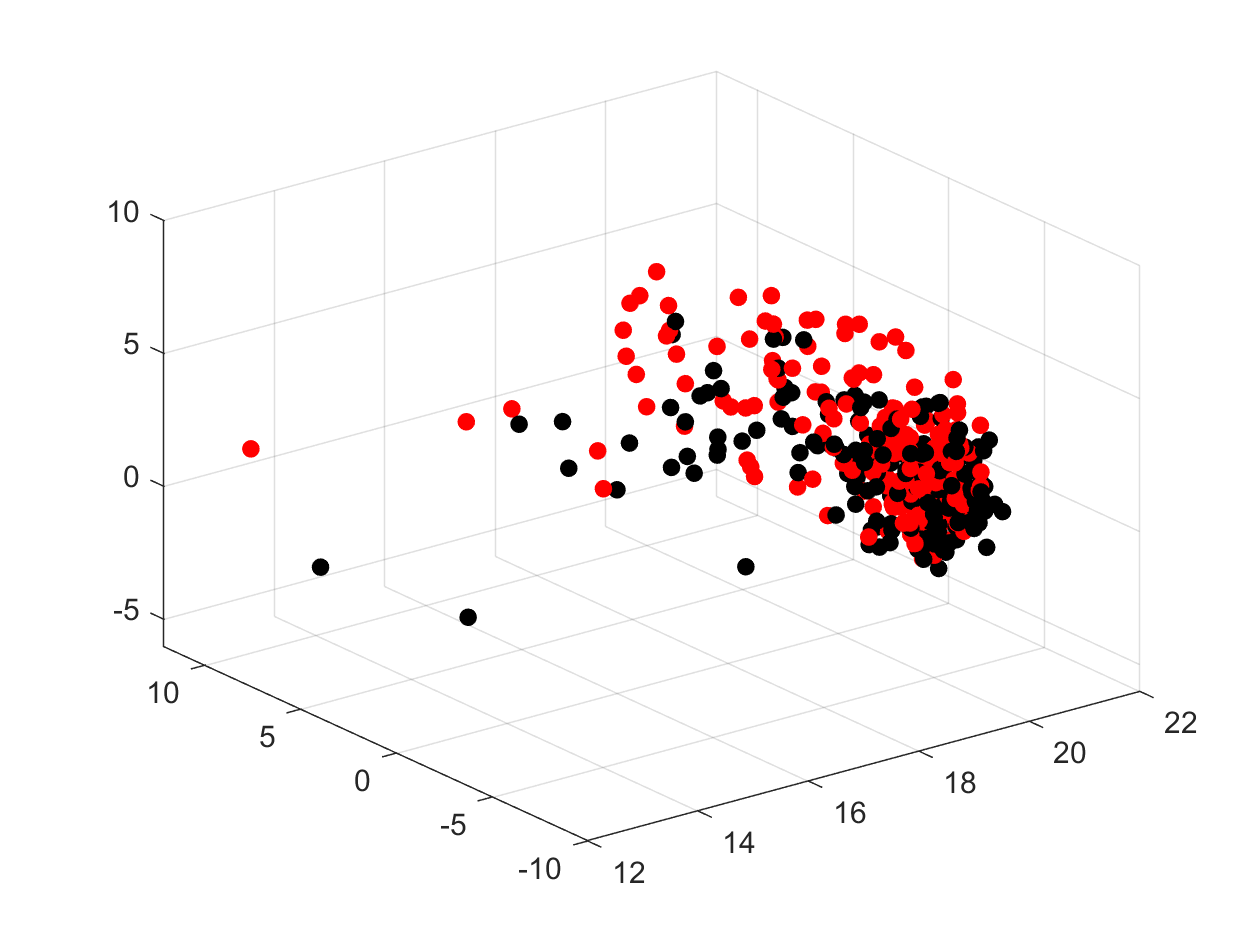

figure;
hold on;
grid;
plot3(Y(D1,1),Y(D1,2),Y(D1,3),'.','Markersize',20,'color','k');
view(3);
plot3(Y(D2,1),Y(D2,2),Y(D2,3),'.','Markersize',20,'color','r');
view(3);



Y1 = Y(D1,:); %projected data of neutral class
Y2 = Y(D2,:); %projected data of smily class

%Test and Train data 
numTrain = 100; %50/50 split best?
numTest = n-numTrain;
train1 = 1:numTrain;
train2 = (n+1):(n+numTrain);
test1 = (numTrain+1):n;
test2 = (n+numTrain+1):(2*n);
train_idx = [train1, train2];
test_idx = [test1, test2];
Ytrain = Y(train_idx,:);
Ytest = Y(test_idx,:);




%Bayesian decision theory
mu1 = mean(Y1,1); %column mean of Y1
mu2 = mean(Y2,1); %column mean of Y2
mea = mean(Ytrain,1);
mean2 = mean(Ytest,1);
fprintf('norm(mea - mean2) = %d\n',norm(mea - mean2));

norm(mea - mean2) = 1.452348e+00


fprintf('norm(mu1-mu2) = %d\n',norm(mu1-mu2));%print mu

norm(mu1-mu2) = 3.214500e+00


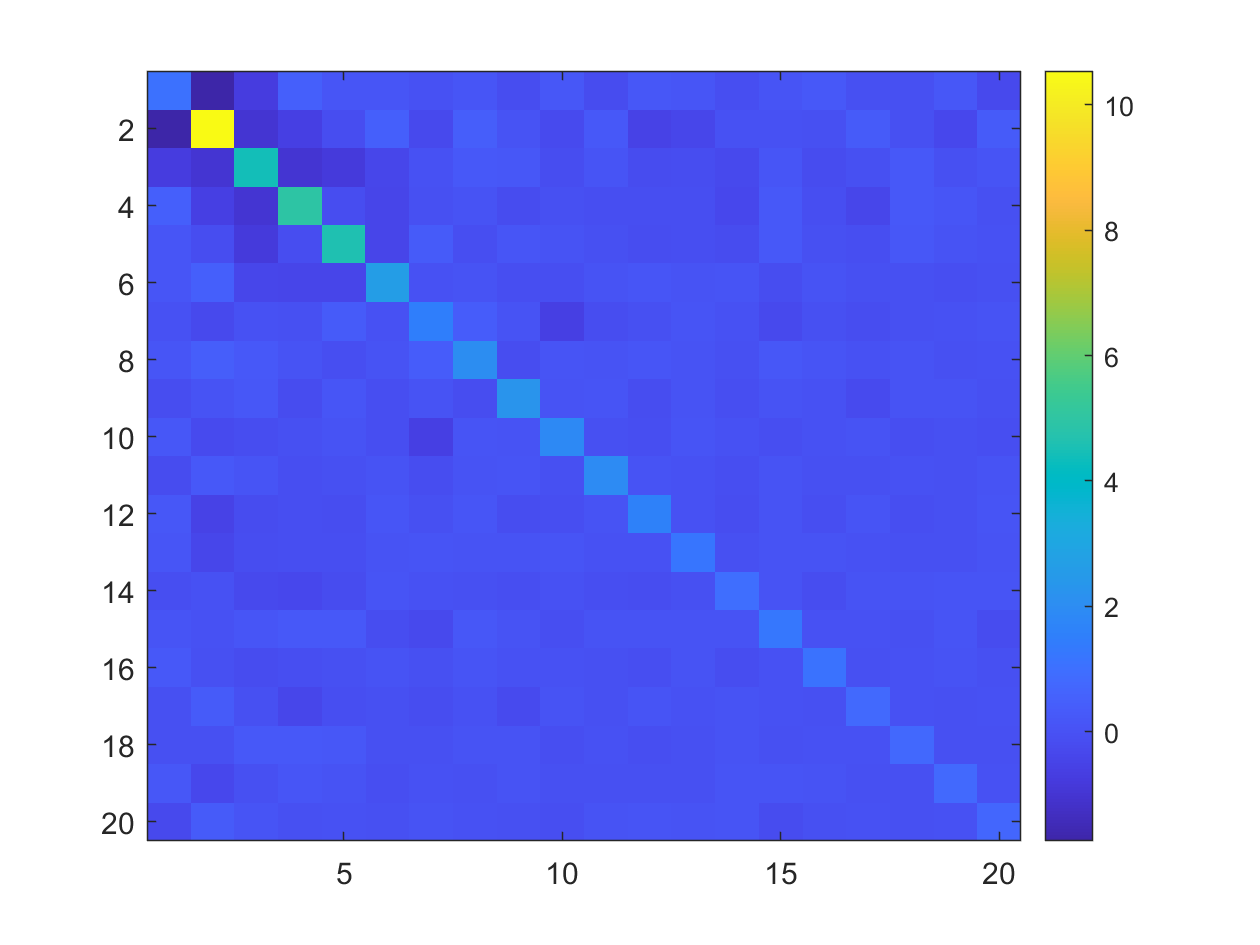


%estimate convariance matrices for each class & center data in each class to compute covariance matrices
Y1c = Y1-ones(n1,1)*mu1; %center the data in class1
Y2c = Y2-ones(n2,1)*mu2; %center the data in class2
S1 = Y1c'*Y1c/n1;
S2 = Y2c'*Y2c/n2;

Yallc = Y1 - ones(n1,1)* mea;
Yallc2 = Y2 - ones(n2,1)*mean2;
newS1 = Yallc'*Yallc/n1;
newS2 = Yallc2'*Yallc2/n2;

figure;
imagesc(newS1);
colorbar;

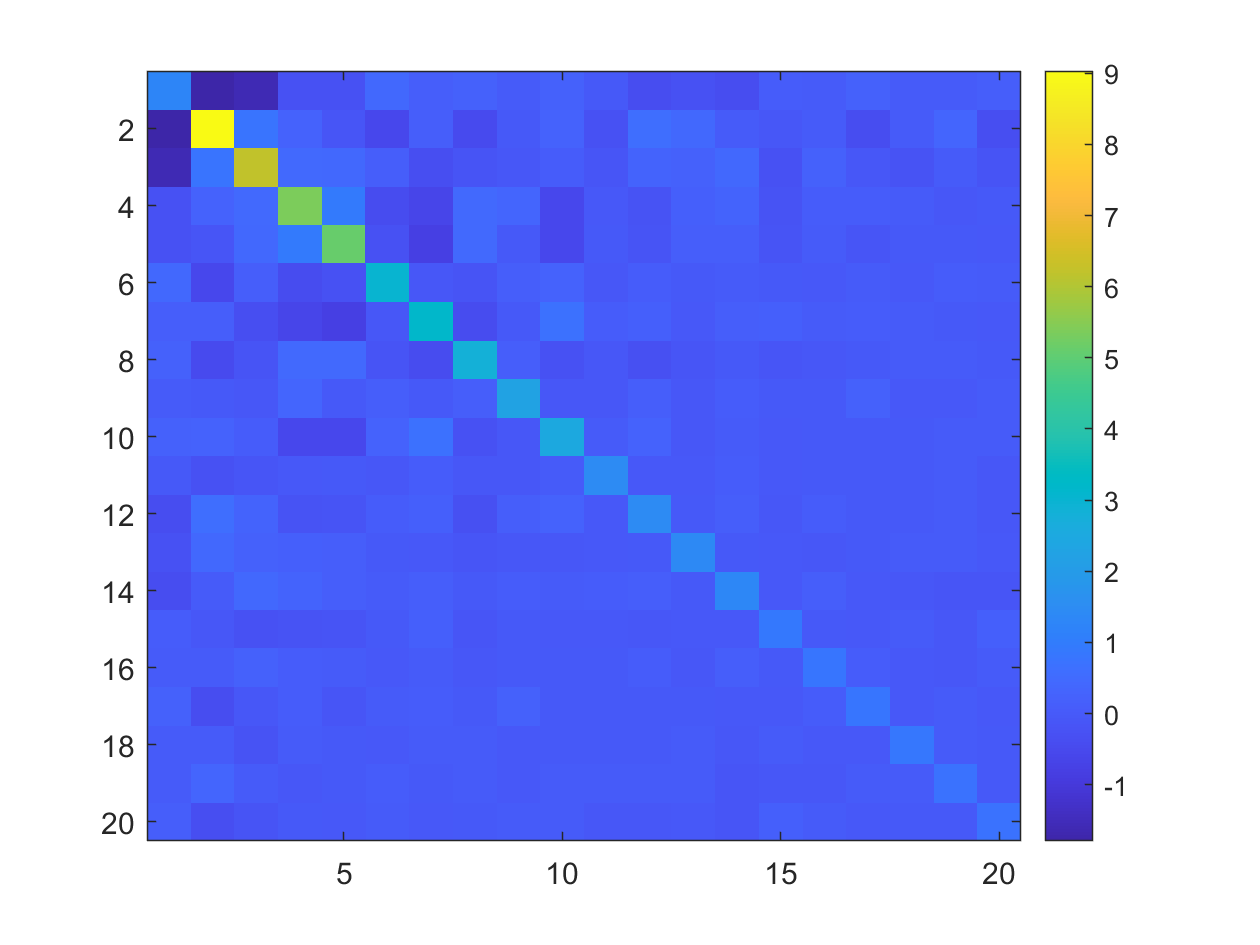


figure;
imagesc(newS2);
colorbar;



%figure;
%imagesc(S1);
%colorbar;
%figure;
%imagesc(S2);
%%colorbar;

%define the discriminant functions

%iS1 = inv(S1);
%%iS2 = inv(S2);
%mu1 = mu1';
%%mu2 = mu2';
%w0 = 0.5*(log(det(S2)/det(S1)))- 0.5*(mu1'*iS1*mu1 - mu2'*iS2*mu2);
%fprintf('w0 = %d\n',w0);
%define the discriminatn functions
newiS1 = inv(newS1);
newiS2 = inv(newS2);
mea = mea';
mean2 = mean2';
w0 = 0.5*(log(det(newS2)/det(newS1)))- 0.5*(mea'*newiS1*mea - mean2'*newiS2*mean2);
fprintf('w0 = %d\n',w0);

w0 = 9.208599e+01



%g = @(x)-0.5*x'*(iS1-iS2)*x+x'*(iS1*mu1-iS2*mu2)+w0;


b = @(x) -0.5*x'*(newiS1-newiS2)*x+x'*(newiS1*mea-newiS2*mean2)+w0;

%classifying the illuminated faces
Y3 = zeros(n,nPCA);
label = zeros(n,1);
for j = 1:n
    aux = face_illum(:,:,j);
    y = (aux(:)'*U(:,1:nPCA))';
    Y3(j,:) = y';
    label(j) = sign(b(y));
end

iplus = find(label > 0);
iminus = find(label < 0);
fprintf('#iplus = %d, #imunus = %d\n',length(iplus),length(iminus));

#iplus = 186, #imunus = 14


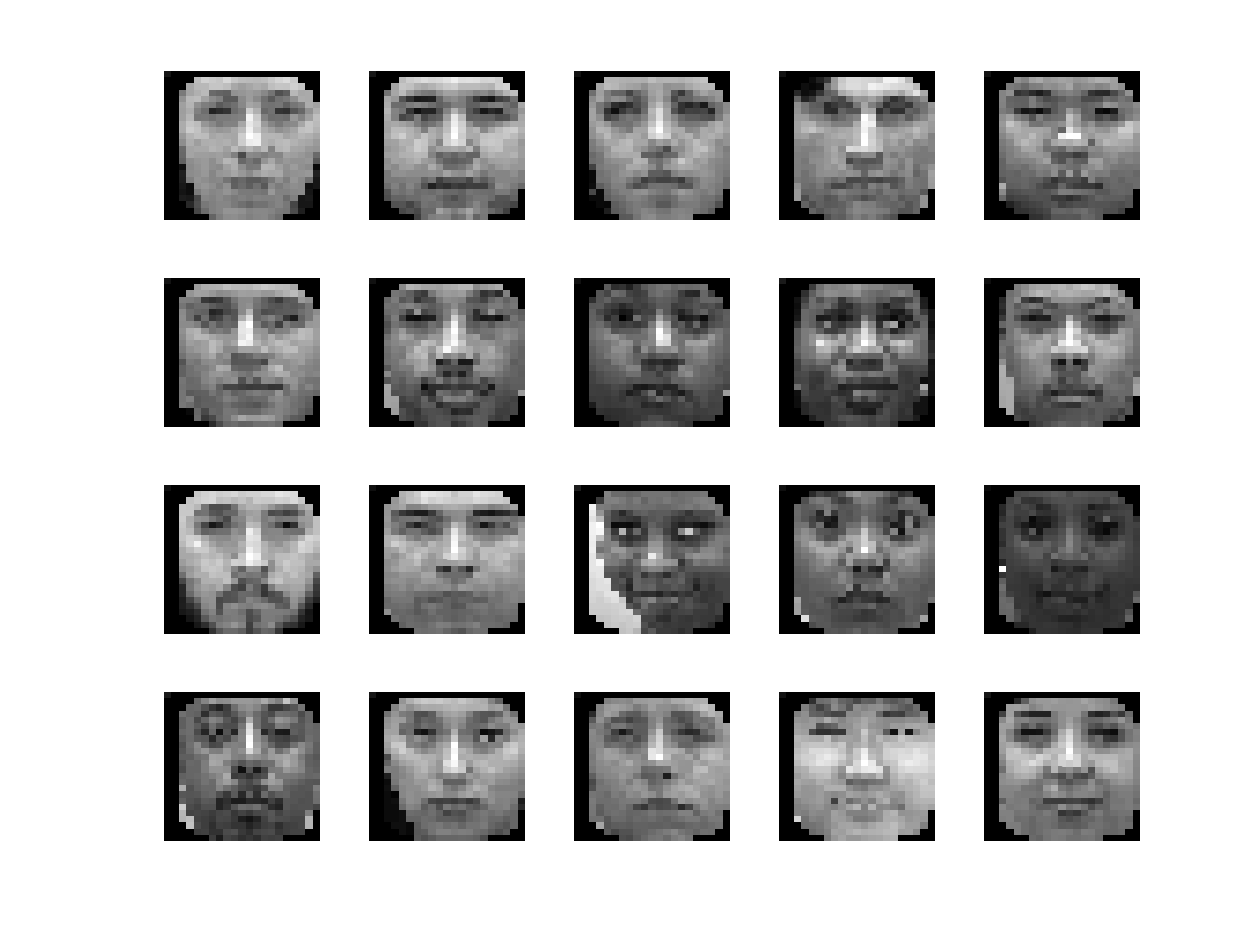

figure;
colormap gray
indl = randperm(length(iplus),20);
for j = 1:20
    subplot(4,5,j);
    imagesc(face_illum(:,:,iplus(indl(j))));
    axis off
end